# Notes regarding lab format

We will use Matlab Livescript for this lab. Livescript allows switching between text and code cells. 

You will find the entire lab manual in this file. Some exercises require you to write a text answer, others require you to write code. You should not define functions inside this file. Instead save functions to the functions folder and call them from the code cells in this notebook.

Your finished lab report should be a .zip-file containing the data folder, your functions folder and this livescript file. As usual, you should also provide a pdf of the result of running the live script (in the Live Editor, you can **export to pdf** under Save) where all result images should be visible.

In certain sections of this lab, MATLAB might throw warnings about conditioning of matrices. You should turn them off using the command  `warning('off','all')` and submit the final pdf without these warnings displayed. 

Since we need to access the functions and data folder the first step is to add these two locations MATLAB's path.

addpath('./functions');
addpath('./data');

# Lab 3 :Image Registration

An affine transformation is written as:


$$\left(\begin{array}{l}
\tilde{x} \\
\tilde{y}
\end{array}\right)=\left(\begin{array}{ll}
a & b \\
c & d
\end{array}\right)\left(\begin{array}{l}
x \\
y
\end{array}\right)+\left(\begin{array}{l}
t_{x} \\
t_{y}
\end{array}\right)=A\left(\begin{array}{l}
x \\
y
\end{array}\right)+t$$


Apart from rotation, translation and scaling, it also allows stretching the image in an arbitrary dimension. 

## Ex 3.1 Getting started

If one would like to stretch the image along the x-axis, one simply applies `A=diag([k,1])` for some stretching factor `k`. How should one obtain a stretching with a factor `k` along a diagonal direction with an affine transformation?

**Write your answer with explanation as a comment here.**

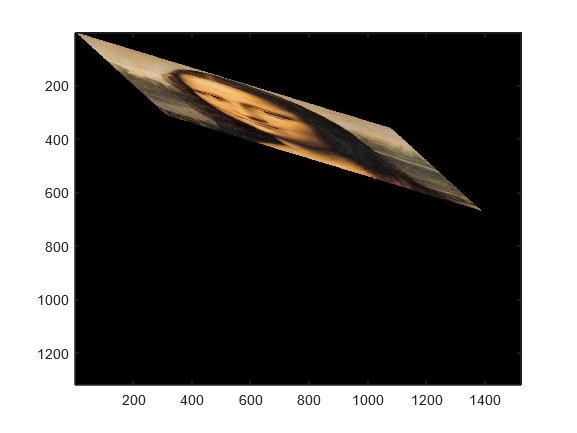

% In order to obtain a diagonal stretch, one can combine a shear
% transformation with a rotation one. In particular, the final affine
% transformation matrix will simply be a multiplication between the two
% matrices (this is possible due to the transformations being indeed
% affine).
img = read_image('./data/mona.png'); 
A_shear = [1 k; 0 1];
A_rot = [cos(pi / 4) -sin(pi / 4); sin(pi / 4) cos(pi / 4)];
A = A_shear * A_rot;
t = [0; 0];
warped = affine_warp(size(img) .* 3, img, A, t);
figure, axis image, imagesc(warped);

## Ex 3.2 Minimum Correspondences

What is the minimal number of point correspondences, K, required in order to estimate an affine transformation between two images?

**Write your answer with explanation as a comment here.**

% K = 3
% 
% The degrees of freedom of the affine transformation is 6 (4 from the
% matrix A and 2 from the translation t).
% Therefore, when rewriting the transformation as a system of linear
% equations, we have the column vector of the parameters of size 1x6.
% 
% In order to estimate the transformation, one can utilize a minimal
% solver, and so stack the starting points in a matrix fashion, which
% can then be multiplied by the paraters vector. In particular, each
% point will account for two rows in the matrix/system of equations.
% Hence, in order to obtain a martix with the minimal rank to solve
% the system (and so determine the transformation), one would need at
% least 3 points, which account for at least six rows (forming a 6x6
% matrix).

In general, an estimation problem where the minimal of amount of data is used to estimate the unknown parameters is called **a minimal problem**.

Once you have found a proper coordinate transformation between two images, you can use the provided function affine_warp to warp the source image and create a warped image. Let’s try it. 

## Ex 3.3 Trying Warping

Load the image mona.png to the variable img. After copying your `read_image `function from previous labs into the *functions* directory, try running the following code snippet :

img = read_image('./data/mona.png'); 
A = [0.88 -0.48; 0.48 0.88]

A =     0.8800   -0.4800
    0.4800    0.8800


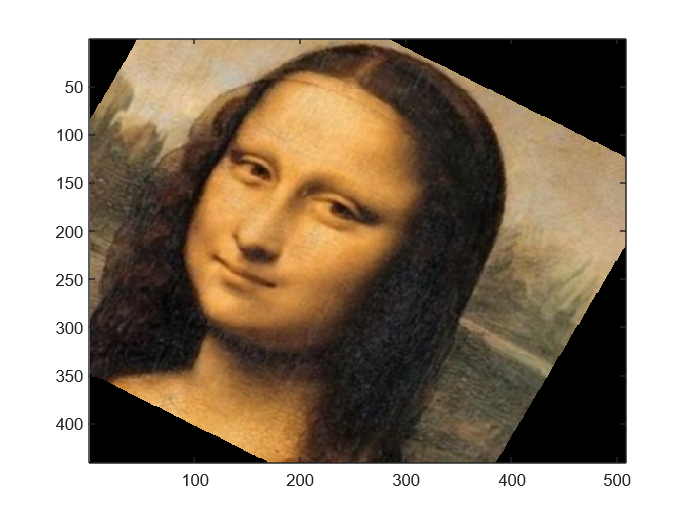

t = [100; -100];
target_size = size(img);
warped = affine_warp(target_size, img, A, t);
figure, axis image, imagesc(warped);

Change the values in A and t to see what happens. First, swap A for eye(2,2) to try a pure translation and plot the result. Then, swap A and t for a stretching along a diagonal as in Ex 3.1 but without rotating and translating the image. Plot the result.

## Your Code here

A = eye(2, 2);
t = [100; 100];
warped = affine_warp(size(img), img, A, t);
disp('INFO. Pure traslation:')

INFO. Pure traslation:


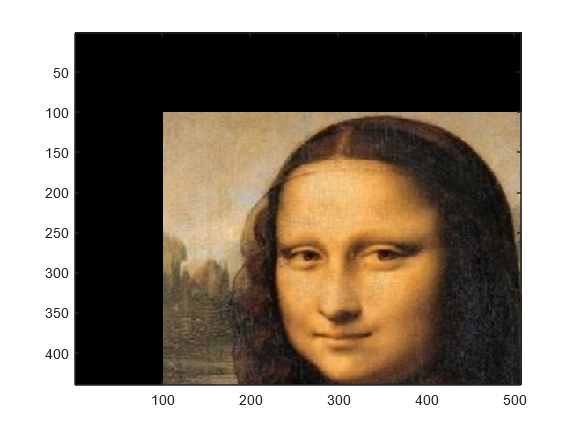

figure, axis image, imagesc(warped);

A_shear = [1 k; 0 1];
A_rot = [cos(pi / 4) -sin(pi / 4); sin(pi / 4) cos(pi / 4)];
A = 0.4 .* A_shear * A_rot;
t = [-10; 10];
warped = affine_warp(size(img), img, A, t);
disp('INFO. Diagonal stretch (and scaled to fit the original size a bit better):')

INFO. Diagonal stretch (and scaled to fit the original size a bit better):


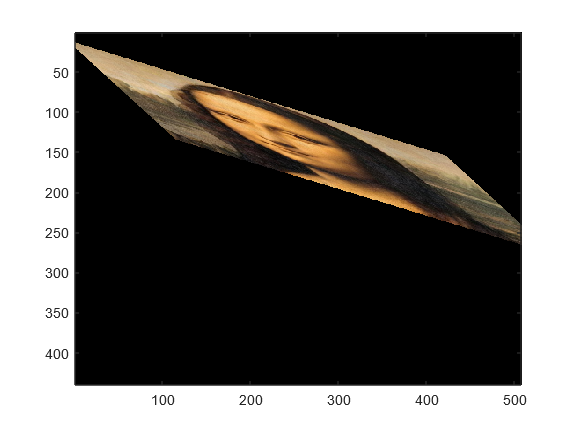

figure, axis image, imagesc(warped);

Explain what you observe in the two cases. **Write your answer as a comment here.**

% Pure traslation: any point (x, y) of the image is transformed into: (x +
% tx, y + ty), therefore the original image appears to be "moved" in a given
% direction.
%
% Diagonal Stretch: the image is stretched along the main diagonal, and so
% it goes "outside" the original image size.

## Ex 3.4 Writing test case			

For any estimation task it is a good idea to have at least one test case where you know what the answer should be. In this exercise, you should make such a test case for RANSAC. Start by generating random points, store them in a variable named `pts`, and a random transformation -` [A_true, t_true]`. Then transform `pts` to create a variable `pts_tilde`. If you want to make it more realistic, add random noise to `pts_tilde`. You now have two sets of points related by a known affine transformation as in *Ex 3.2*. In the following exercises you will try to estimate this transformation. As you know the correct answer it is easy to detect if you make a mistake. 					

**Make a function** 

that generates a test case for estimating an affine transformation. The transformation should transform `pts` to `pts_tilde.` Don't add any gross outliers. Outputs `pts` and `pts_tilde` should be `2 x N-arrays`. Also output the *true* transformation, so you know what to expect from your code.

After you have written the function, test it with a few runs. **Your code here:**

## Your code here

k = 3;
[pts, pts_tilde, A_true, t_true] = affine_test_case(k);

pts

pts =     0.2785    0.9575    0.1576
    0.5469    0.9649    0.9706


pts_test = A_true * pts + t_true;
disp(['INFO. Average absolute error: ' num2str(mean(abs(pts_test - pts_tilde), 'all'))])

INFO. Average absolute error: 0


## Ex 3.5 Writing a minimal solver

Make a minimal solver for the case of affine transformation estimation. In other words, **make a function**

that estimates an affine trasnformation mapping `pts` to `pts_tilde`, where `pts` and `pts_tilde` are `2 x K - arrays` and `K` is the number you found in *Ex 3.2*. Try your function on points from the test case in *Ex 3.4*. **Your code here:**

[A, t] = estimate_affine(pts, pts_tilde)

A =     0.8147    0.1270
    0.9058    0.9134


t =     6.3236
    0.9754


disp(['INFO. Average difference of A: ' num2str(mean(abs(A - A_true), 'all'))])

INFO. Average difference of A: 2.8449e-16


disp(['INFO. Average difference of t: ' num2str(mean(abs(t - t_true), 'all'))])

INFO. Average difference of t: 4.996e-16


## Ex 3.6 Computing residuals

Make a function

that computes the lengths of 2D residual vectors. The function should return an array with N values. *Hint : *Given a `2 x N` matrix, stored in `M`, the column-wise sum of the **squared** elements can be computed as `sum(M.^2, 1)`. 

**Verify** that for no outliers and no noise, you get zero residual lengths given the true transformation:

k = 100;
outlier_rate = 0.3;
noise_magnitude = 0.01;
% Generate samples with no noise and no outliers
[pts, pts_tilde, A, t] = affine_test_case(k);
disp(['INFO. Number of residuals: ' num2str(residual_lgths(A, t, pts, pts_tilde))])

INFO. Number of residuals: 0


% Generate samples with noise and no outliers
[pts, pts_tilde, A, t] = affine_test_case(k, noise_magnitude);
disp(['INFO. Number of residuals: ' num2str(residual_lgths(A, t, pts, pts_tilde))])

INFO. Number of residuals: 100


## **Ex 3.7 Test case with outliers**

Modify your function `affine_test_case `to create a new function `affine_test_case_outlier `that takes a parameter `outlier_rate` and produces a fraction of outliers among the output points. For example, if `outlier_rate` is 0.2, then 80% of the samples will be related by `pts_tilde = A_true * pts + t_true`. While for the remaining 20%, pts_tilde can be distributed uniformly within some range. 

**Test your code here:**

% Generate samples with no noise and outliers
[pts, pts_tilde, A, t] = affine_test_case_outlier(outlier_rate, k);
disp(['INFO. Number of residuals: ' num2str(residual_lgths(A, t, pts, pts_tilde))])

INFO. Number of residuals: 30


% Generate samples with noise and outliers
[pts, pts_tilde, A, t] = affine_test_case_outlier(outlier_rate, k, noise_magnitude);
disp(['INFO. Number of residuals: ' num2str(residual_lgths(A, t, pts, pts_tilde))])

INFO. Number of residuals: 100


## **Ex 3.8 Writing a RANSAC based solver**

Make a function					

that uses RANSAC to find an affine transformation between two sets of points. (Like before the transformation should map `pts` to `pts_tilde`.) Test your function on test cases generated with your function `affine_test_case_outlier`. 

**RANSAC Note** : You can use the notes to decide on the number of RANSAC iterations needed given your required confidence and estimated inlier ratio. You can also use fixed iterations but make sure that you have enough iterations to find a reasonable solution.

**Verify your code here**. Try different outlier rates. Make sure that you get the right transformation for a reasonable outlier rate as well. 

thresh = 2;
outlier_rate = 0.4;
k = 100;
noise_magnitude = 0.00001;
[pts, pts_tilde, A_true, t_true] = affine_test_case_outlier(outlier_rate, k, noise_magnitude);
A_true

A_true =     0.9223    0.0427
    0.7710    0.3782


t_true

t_true =     7.0434
    7.2951


[A_min_solv, t_min_solv] = estimate_affine(pts, pts_tilde);
disp(['INFO. Minimal Solver. Avg diff of A: ' num2str(mean(abs(A_min_solv - A_true), 'all'))])

INFO. Minimal Solver. Avg diff of A: 8.3126


disp(['INFO. Minimal Solver. Avg diff of t: ' num2str(mean(abs(t_min_solv - t_true), 'all'))])

INFO. Minimal Solver. Avg diff of t: 13.7048


[A_est, t_est] = ransac_fit_affine(pts, pts_tilde, thresh);
disp(['INFO. RANSAC. Avg diff of A: ' num2str(mean(abs(A_est - A_true), 'all'))])

INFO. RANSAC. Avg diff of A: 1.2788e-05


disp(['INFO. RANSAC. Avg diff of t: ' num2str(mean(abs(t_est - t_true), 'all'))])

INFO. RANSAC. Avg diff of t: 1.7026e-05


## Ex 3.9 Aligning Images

For this exercise, you should use the function

from *Lab 1* to extract SIFT features. Note that it only works for grayscale images, so if you have a colour image you need to convert it to grayscale before using `extractSIFT`. To match features you can use the built-in function matchFeatures. To use the Lowe criterion (with threshold 0.8) you should use the following options: 

**Write a function**

that uses SIFT and RANSAC to align the `source` image to the `target` image with `thresh` as the residual threshold for counting inliers in your RANSAC. To perform the actual warping, use the `affine_warp` function within your `align_images` function. Be very careful about the order in which you send the points to RANSAC.

**Align **`vermeer_source.png` to `vermeer_target.png using` your `align_images` function. Plot the source, target and warped source images together.

rng(2); % Set random seed for reproducibility
threshold = 30;
n_samples = 3;
img_src = read_as_grayscale('./data/vermeer_source.png');
img_tgt = read_as_grayscale('./data/vermeer_target.png');

warped = align_images(img_src, img_tgt, threshold, n_samples);
disp('INFO. Source image:')

INFO. Source image:


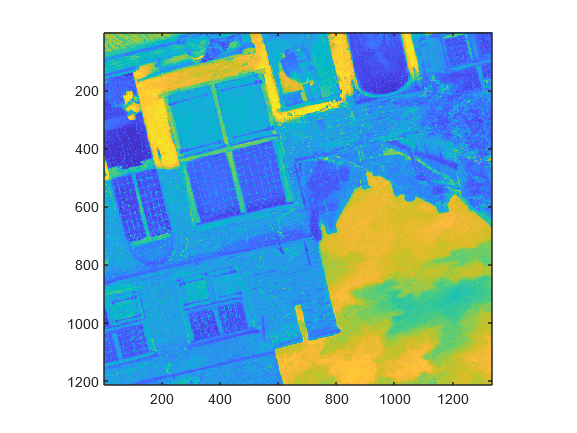

figure, imagesc(img_src); axis image

disp('INFO. Target image:')

INFO. Target image:


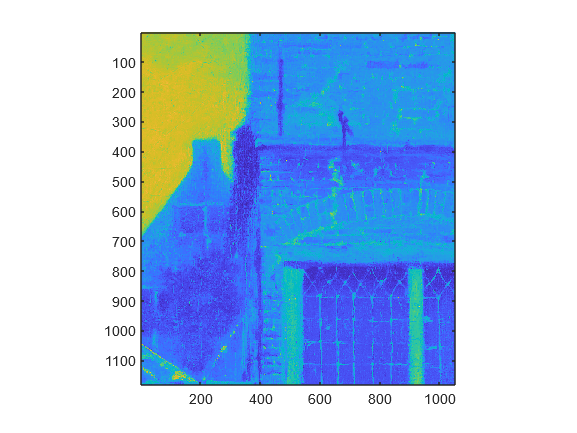

figure, imagesc(img_tgt); axis image

disp('INFO. Warped image:')

INFO. Warped image:


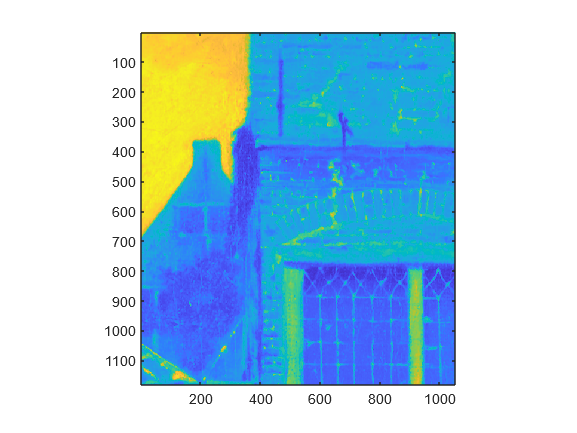

figure, imagesc(warped); axis image

## Ex 3.10 Aligning Images with known orientation

Medical images often have less local structure, making SIFT matching more difficult. It often works better if we drop the rotation invariance. The provided `extractSIFT` function has an option for this. 

assumes that the image has a default orientation. Plot the warped and the target images next to each other to verify your result. Modify your `align_images` function to create function `align_images_v2 `so that it also takes a boolean argument, `upright` stating whether the images have the same orientation, i.e. 

Try aligning the images *CT_1.jpg* and *CT_2.jpg*. Try with and without rotation invariance at different outlier thresholds. Also plot the warped image and the target image next to each other so one can verify the result (if successful).

INFO. Threshold: 20, upright: 1


WARNING. Maximum number of iterations reached.


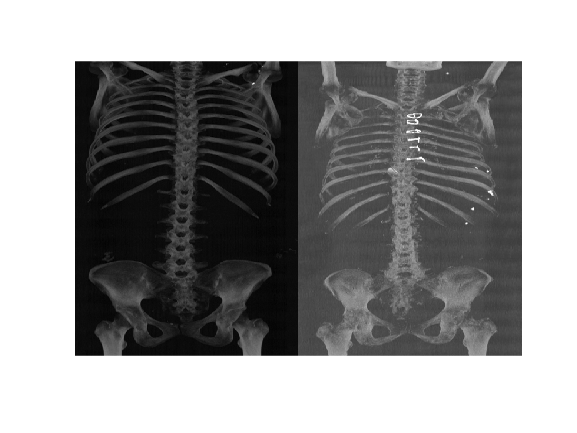

INFO. Threshold: 30, upright: 1


WARNING. Maximum number of iterations reached.


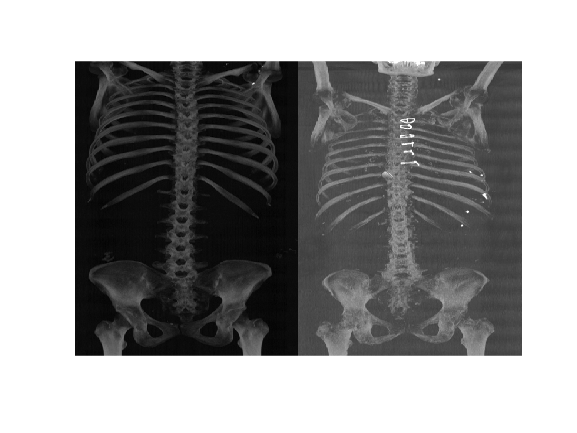

INFO. Threshold: 40, upright: 1


WARNING. Maximum number of iterations reached.


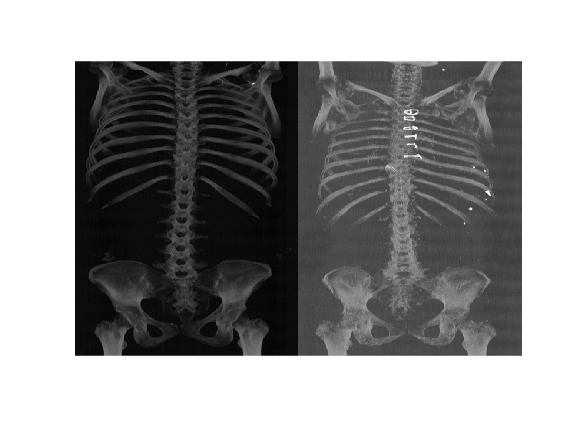

INFO. Threshold: 100, upright: 1


WARNING. Maximum number of iterations reached.


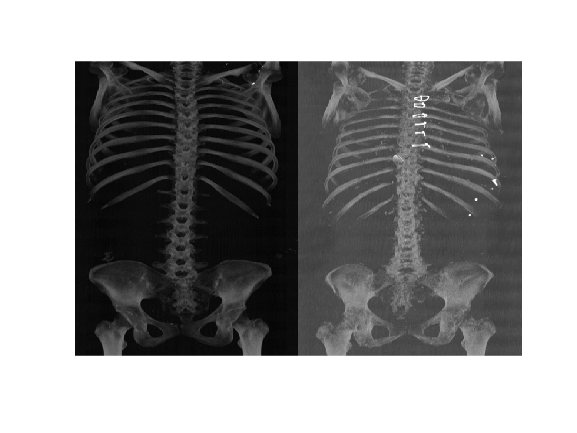

INFO. Threshold: 20, upright: 0


WARNING. Maximum number of iterations reached.


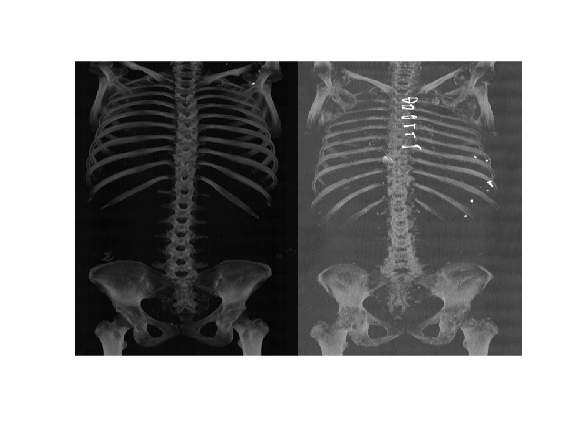

INFO. Threshold: 30, upright: 0


WARNING. Maximum number of iterations reached.


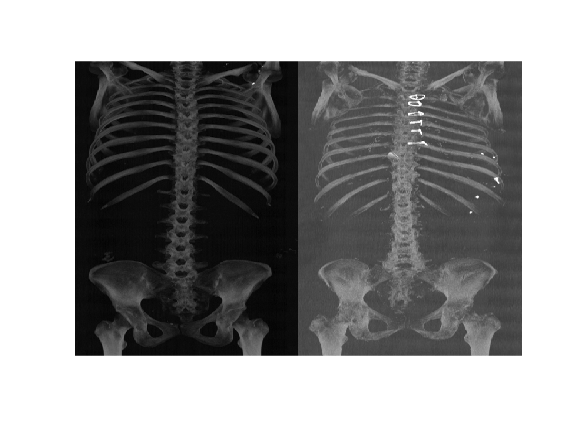

INFO. Threshold: 40, upright: 0


WARNING. Maximum number of iterations reached.


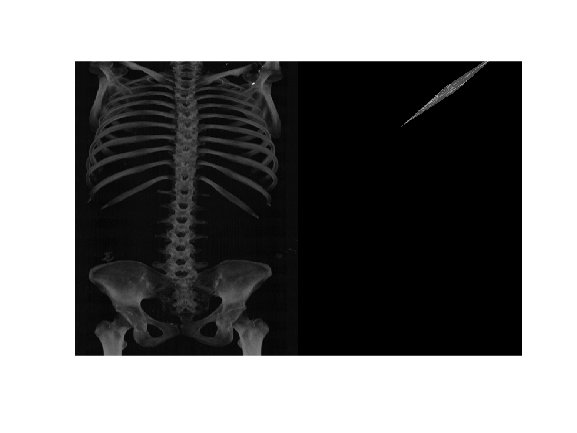

INFO. Threshold: 100, upright: 0


WARNING. Maximum number of iterations reached.


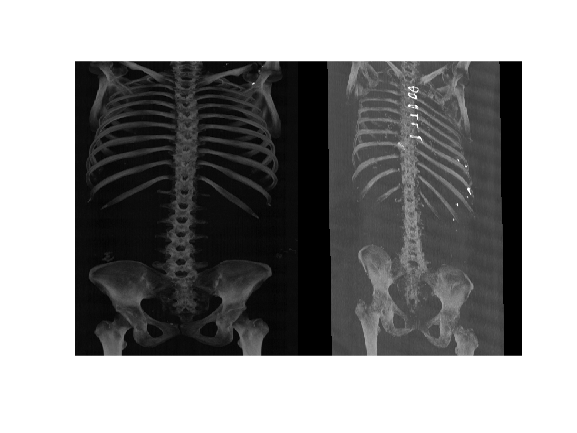

rng(2); % Set random seed for reproducibility
n_samples = 6;
img_src = read_as_grayscale('./data/CT_1.jpg');
img_tgt = read_as_grayscale('./data/CT_2.jpg');
for upright = [true, false]
    for thresh = [20, 30, 40, 100]
        disp(['INFO. Threshold: ' num2str(thresh) ', upright: ' num2str(upright)])
        warped = align_images_v2(img_src, img_tgt, thresh, upright, n_samples);
        figure, montage([img_tgt, warped])
    end
end

**Explain your observations of using and not using rotation invariance at differnt thresholds here.**

% When dropping the rotation invariance (upright=true), we can visually
% notice that the warped image is aligned correctly even with lower values
% of threshold.
% On the other end, when the rotation is included, some of the results are
% not sufficiently "pleasant" for high threshold values.

## Ex 3.11 Flourescent Image example

Try aligning *tissue_fluorescent.tif *and *tissue_brightfield.tif*. In the fluorescent image, the intensities are basically inverted, so you need to invert one of the images before computing descriptors. (Otherwise you won’t get any good matches.) If you used `read_as_grayscale` to load the images, they should have values between 0 and 1 so you can invert it by taking 

Plot the warped image and the target image side by side so one can verify the result.

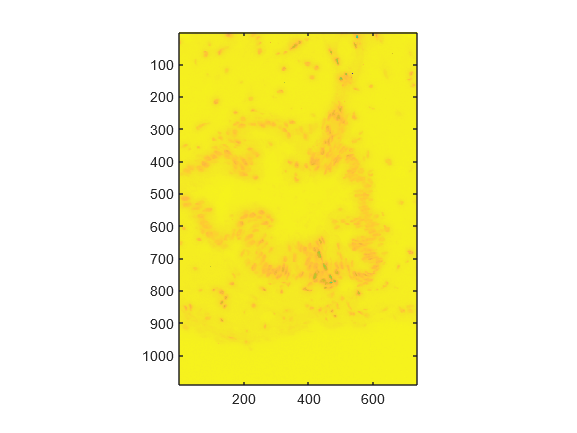

rng(2); % Set random seed for reproducibility
threshold = 70;
n_samples = 3;
upright = true;
img_src = read_as_grayscale('./data/tissue_fluorescent.tif');
img_tgt = read_as_grayscale('./data/tissue_brightfield.tif');
% NOTE: Luckily, normalization is not needed
norm_data = @(x) (x - min(x)) ./ (max(x) - min(x));
img_src = 1 - img_src;
warped = align_images_v2(img_src, img_tgt, threshold, upright, n_samples);
figure, imagesc(img_src); axis image

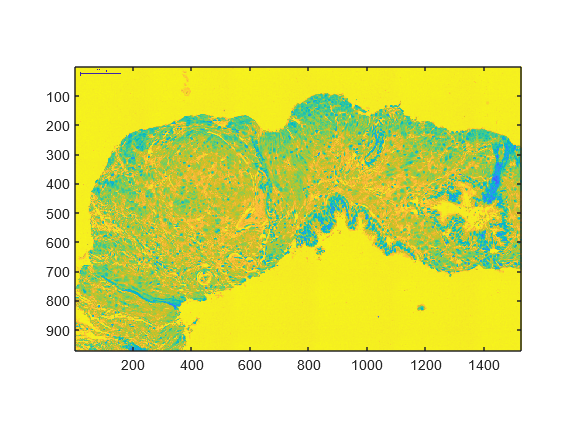

figure, imagesc(img_tgt); axis image

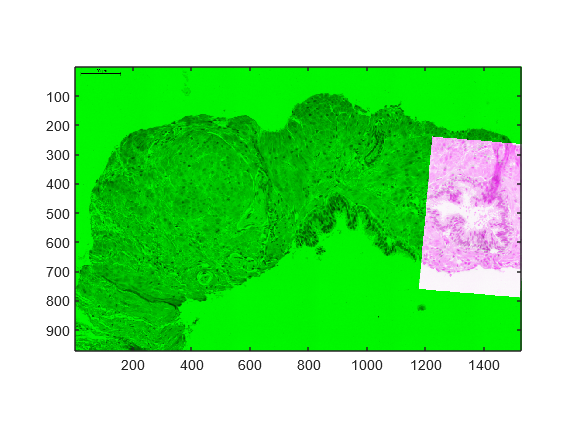

figure, imagesc(imfuse(img_tgt, warped)); axis image

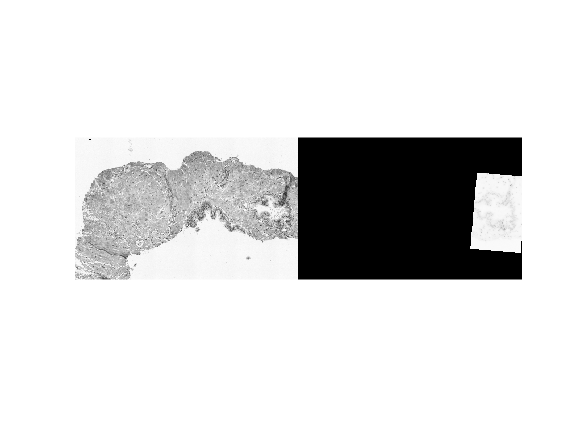

figure, montage([img_tgt, warped])

# Warping

## Ex 3.12 Get Pixel value

So far you have used Matlab's function for warping. The reason is that it is difficult to write a Matlab function for warping that is not painfully slow. Now you will get to write one anyway, but we will only use it for very small images. 

**Write a function**

that gives you the pixel value at `position`. If the elements of `position` are not integers, select the value at the closest pixel. If it is outside the image, return 1 (=white). Try your function on a simple image to make sure it works.

A = [0.1 0.2 3; 4 5 0.6; 2 0.7 9]

A =     0.1000    0.2000    3.0000
    4.0000    5.0000    0.6000
    2.0000    0.7000    9.0000


sample_image_at(A, [1.2, 2.7])

ans = 3

sample_image_at(A, [2.35, 2.7])

ans = 0.6000

sample_image_at(A, [1.2, 0])

ans = 1

## Ex 3.13 Warp 

Now, you will do a warping function that warps a `16 x 16` image according to the coordinate transfomation provided in `transform_coordinates.m`. 

Write a function 

that warps source according to `transform_coordinates` and forms an output `16 X 16` image warped. Use your function `sample_image_at` to extract pixel values. Try the function on `source_16x16.tif` and plot the answer using imagesc. You will get to see a meaningful image if you get it right.

## Your code here

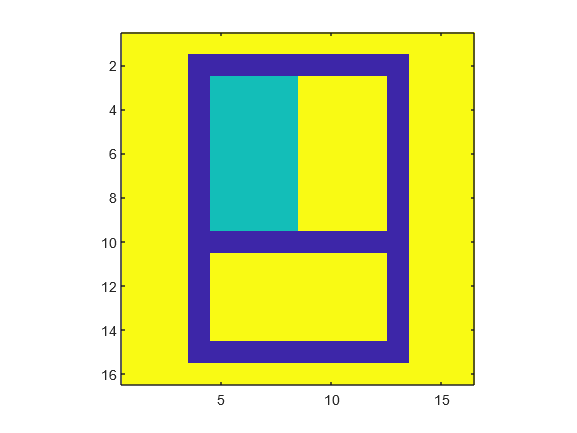

source = read_as_grayscale('./data/source_16x16.tif');
warped = warp_16x16(source);
figure, imagesc(source); axis image

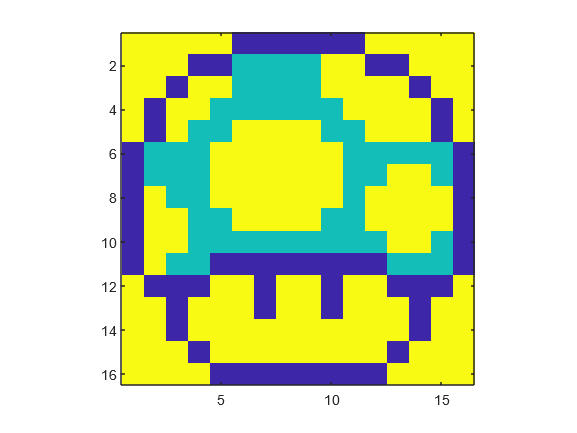

figure, imagesc(warped); axis image

# Least Squares

## Ex 3.15 Least squares

Write a function

that estimates an affine transformation mapping `pts` to `pts_tilde `in least squares sense, i.e., all points in `pts` and `pts_tilde` are used to compute the transformation. (Depending on how you wrote you estimate_affine.m, this might be very easy.) Use it on the inliers from RANSAC to refine the estimate. Add this to `align_images `to form a new function` align_images_inlier_ls` and test it on the `Vermeer` images for different outlier thresholds. Plot the final result images next to each other.

INFO. Threshold: 1


INFO. Running RANSAC with minimal solver.


INFO. Number of inliers: 158
INFO. Mean residual: 1481904.3045


INFO. Running RANSAC with least squares solver.


WARNING. Maximum number of iterations reached.
INFO. Number of inliers: 146
INFO. Mean residual: 1481169.9315


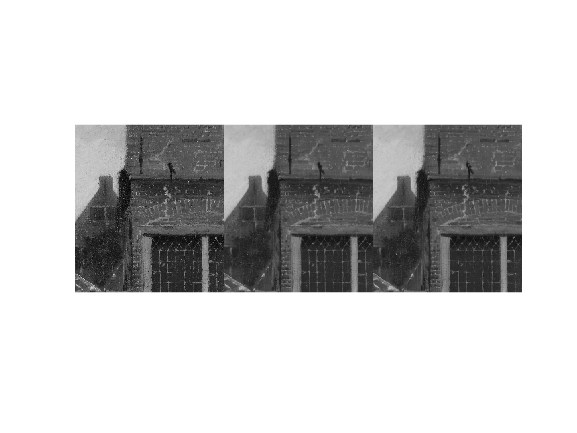

INFO. Threshold: 15


INFO. Running RANSAC with minimal solver.


INFO. Number of inliers: 320
INFO. Mean residual: 1476678.9977


INFO. Running RANSAC with least squares solver.


WARNING. Maximum number of iterations reached.
INFO. Number of inliers: 363
INFO. Mean residual: 1479705.4259


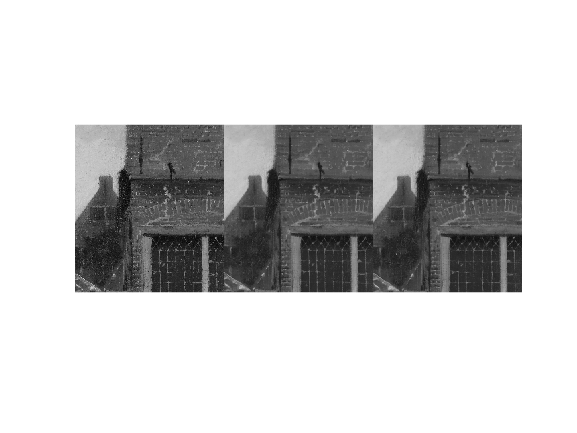

INFO. Threshold: 30


INFO. Running RANSAC with minimal solver.


INFO. Number of inliers: 326
INFO. Mean residual: 1489520.7259


INFO. Running RANSAC with least squares solver.


INFO. Number of inliers: 382
INFO. Mean residual: 1480781.9093


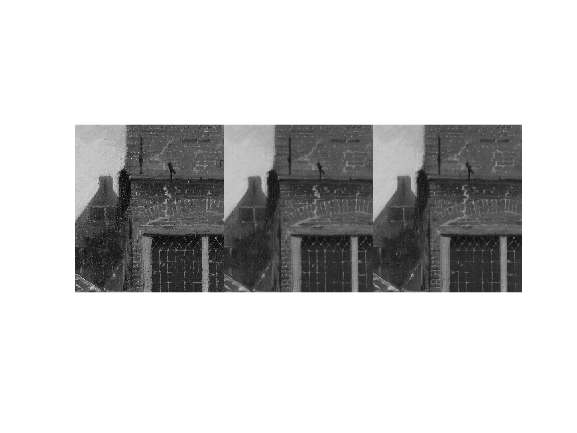

INFO. Threshold: 70


INFO. Running RANSAC with minimal solver.


INFO. Number of inliers: 392
INFO. Mean residual: 1480514.2794


INFO. Running RANSAC with least squares solver.


INFO. Number of inliers: 392
INFO. Mean residual: 1477370.8672


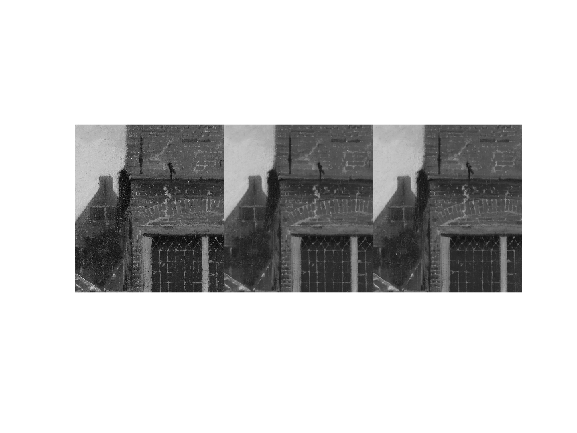

INFO. Threshold: 100


INFO. Running RANSAC with minimal solver.


INFO. Number of inliers: 395
INFO. Mean residual: 1480468.0794


INFO. Running RANSAC with least squares solver.


INFO. Number of inliers: 395
INFO. Mean residual: 1478785.2916


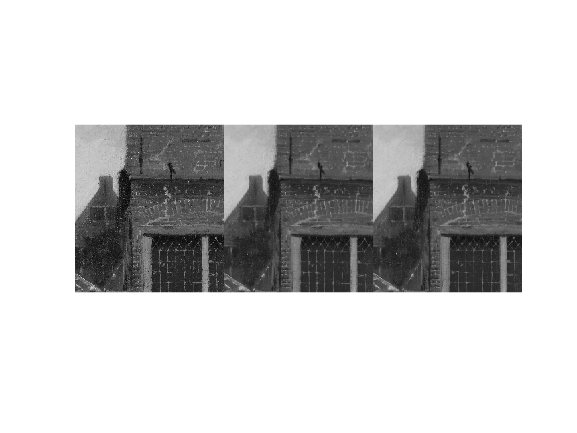

% NOTE: Indeed my initial implementation of 'estimate_affine' did consider
% all the given points. Because of that, for this exercise, I increased the
% number of sample points, bringing it from 3 (the minimum) to a higher
% number (like 10 in this case).
% NOTE: The function 'align_images_inlier_ls' is basically the same as in
% the exercise above, since it's anyway generic. The same applies to my
% RANSAC implementation.
rng(2); % Set random seed for reproducibility
n_samples = 10;
upright = false;
img_src = read_as_grayscale('./data/vermeer_source.png');
img_tgt = read_as_grayscale('./data/vermeer_target.png');
for threshold = [1, 15, 30, 70, 100]
    disp(['INFO. Threshold: ' num2str(threshold)])
    disp('INFO. Running RANSAC with minimal solver.')
    warped = align_images_inlier_ls(img_src, img_tgt, threshold, upright, 3);
    disp('INFO. Running RANSAC with least squares solver.')
    warped_lstsq = align_images_inlier_ls(img_src, img_tgt, threshold, upright, n_samples);
    figure, montage([img_tgt, warped, warped_lstsq])
end

INFO. Threshold: 1


INFO. Running RANSAC with minimal solver.


INFO. Number of inliers: 346
INFO. Mean residual: 113969.1348


INFO. Running RANSAC with least squares solver.


INFO. Number of inliers: 343
INFO. Mean residual: 113987.9825


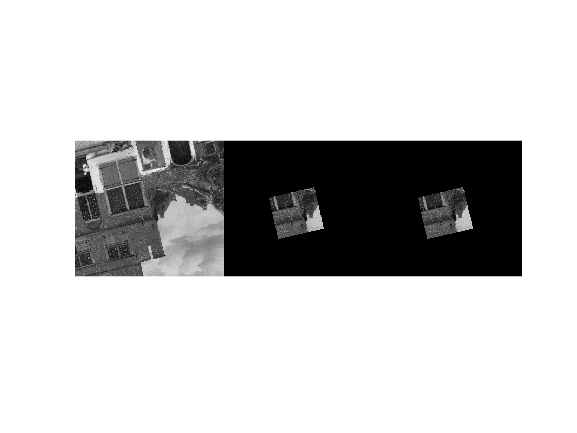

INFO. Threshold: 15


INFO. Running RANSAC with minimal solver.


INFO. Number of inliers: 400
INFO. Mean residual: 113930.0569


INFO. Running RANSAC with least squares solver.


INFO. Number of inliers: 402
INFO. Mean residual: 113991.0371


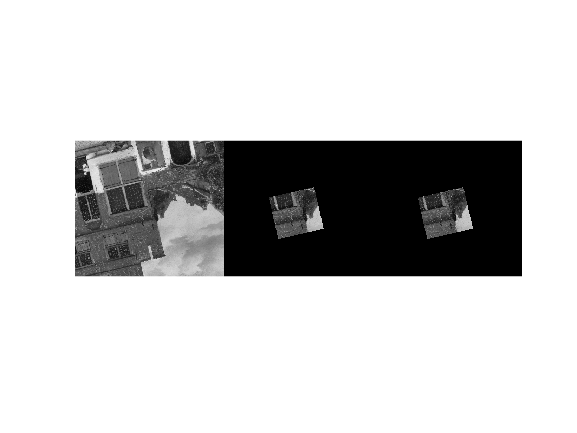

INFO. Threshold: 30


INFO. Running RANSAC with minimal solver.


INFO. Number of inliers: 406
INFO. Mean residual: 114035.9933


INFO. Running RANSAC with least squares solver.


INFO. Number of inliers: 405
INFO. Mean residual: 113954.2839


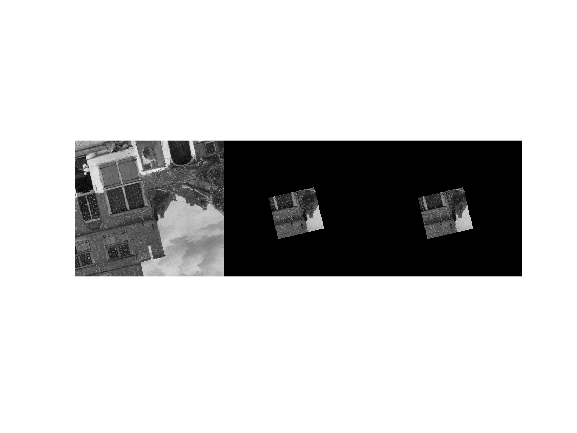

INFO. Threshold: 70


INFO. Running RANSAC with minimal solver.


INFO. Number of inliers: 409
INFO. Mean residual: 113995.2669


INFO. Running RANSAC with least squares solver.


INFO. Number of inliers: 409
INFO. Mean residual: 114004.8756


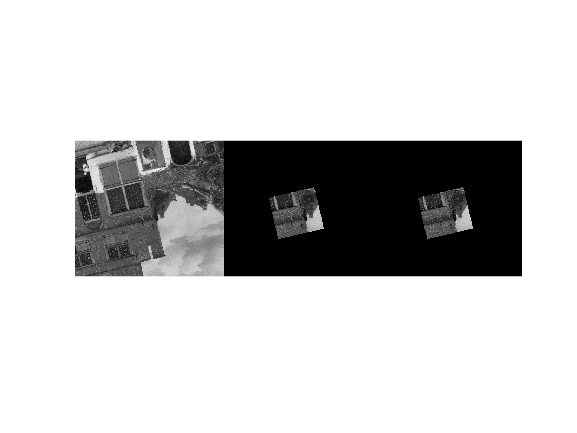

INFO. Threshold: 100


INFO. Running RANSAC with minimal solver.


INFO. Number of inliers: 410
INFO. Mean residual: 113987.9144


INFO. Running RANSAC with least squares solver.


INFO. Number of inliers: 410
INFO. Mean residual: 114019.2083


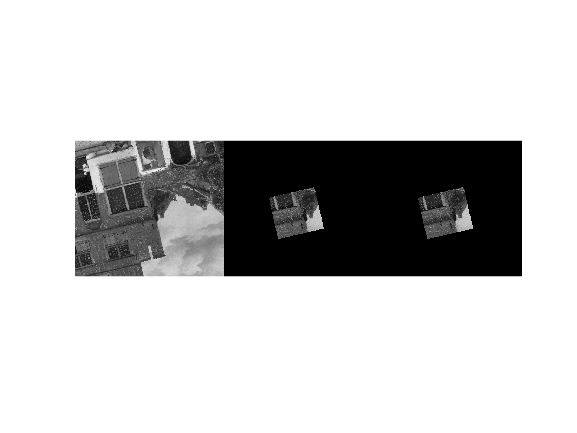

for threshold = [1, 15, 30, 70, 100]
    disp(['INFO. Threshold: ' num2str(threshold)])
    disp('INFO. Running RANSAC with minimal solver.')
    warped = align_images_inlier_ls(img_tgt, img_src, threshold, upright, 3);
    disp('INFO. Running RANSAC with least squares solver.')
    warped_lstsq = align_images_inlier_ls(img_tgt, img_src, threshold, upright, n_samples);
    figure, montage([img_src, warped, warped_lstsq])
end

Do you notice an improvement? Observe visually and also in terms of the residuals. **Explain your observations and the plausible reasons behind them as comment here.**

% I don't see a particular difference, but it seems that for lower outliers
% threshold, RANSAC with least squares is able to identify more inliers.
% This could be due to the use of the least square-solver, as it is more
% robust against the outliers.